# Algebraic differentiators (How to use the implementation)

This live script includes a detailed introduction into the theoretical background of algebraic differentiators and shows how to use the proposed implementation.

## Theoretical background

The algebraic derivative estimation methods were initially derived using differential algebraic manipulations of truncated Taylor series (Mboup 2007, 2009). Later works (Liu 2011, Kiltz 2017) derived these filters using an approximation theoretical approach that yields a straightforward analysis of the filter characteristics, especially the estimation delay. Using this approach, the estimate of the $n$-th order derivative of a signgal $t \mapsto y(t)$ denoted $\hat{y}^{(n)}$ can be approximated as


$$\hat{y}^{(n)} (t) = \int_{0}^{T} g_T^{(n)}(\tau)y(t-\tau) d\tau$$


with the filter kernel


$$g_T(t) = \frac{2}{T} \sum_{t=0}^{N} \frac{P_i^{(\alpha, \beta)}(\vartheta)}{\|P_i^{(\alpha, \beta)}\|^2}w^{(\alpha, \beta)}(v(t))P_i^{(\alpha,\beta)}(v(t)).$$


In the latter equation

- $\nu(t) = 1-\frac{2}{T}$,

- $\|x\| = \sqrt{\langle x,x \rangle}$ is the norm induced by the inner product $\langle x,y\rangle=\int_{-1}^{1}w^{(\alpha,\beta)}(\tau)x(\tau){y(\tau)}\textrm{d}\tau$, with the weight function 

                        
$$
        w^{(\alpha,\beta)}(\tau)=\begin{cases}
        (1-\tau)^\alpha(1+\tau)^\beta,&\quad\tau\in[-1,1],\\
        0,&\quad\text{otherwise},
        \end{cases}$$


- $N$ is the degree of the polynomial approximating the signal $y^{(n)}$ in the time window $[t-T,t]$,

- $T$ is the filter window length,

- and $\vartheta$ parameterizes the estimation delay as described in the following equation.

This approach yields a straightforward analysis of the estimation delay $\delta_1$ and the degree of exactness $\gamma$. The degree of exactness was introduced in (Kiltz 2017) as the polynomial degree up to which the derivative estimation is exact. If $\gamma = 2$ for example, the first and second time derivatives of a polynomial signal of degree two are exact up to an estimation delay. The delay and the degree of exactness are given as 


$$\gamma =\left\lbrace \begin{array}{ll}
n+N+1, & \textrm{if}\;N=0\;\vee \vartheta =p_{N+1,k}^{\left(\alpha ,\;\beta \;\right)} \\
n+N, & \textrm{otherwise},
\end{array}\right.$$



$$\delta_1 =\left\lbrace \begin{array}{ll}
\;\frac{\alpha +1}{\alpha +\beta \;+2}T, & \textrm{if}\;N=0\\
\frac{\;1-\vartheta \;}{2}T, & \textrm{otherwise},
\end{array}\right.$$


with $p_{N+1,k}^{\left(\alpha \;,\beta \;\right)}$ the $k$-th zero of the Jacobi polynomial of degree $N+1$.

## Time-domain analysis

The parameter $\vartheta$ is initialized by default as the largest zero of the Jacobi polynomial of degree $N+1$. This can be changed using the appropriate class member function (see documentation).

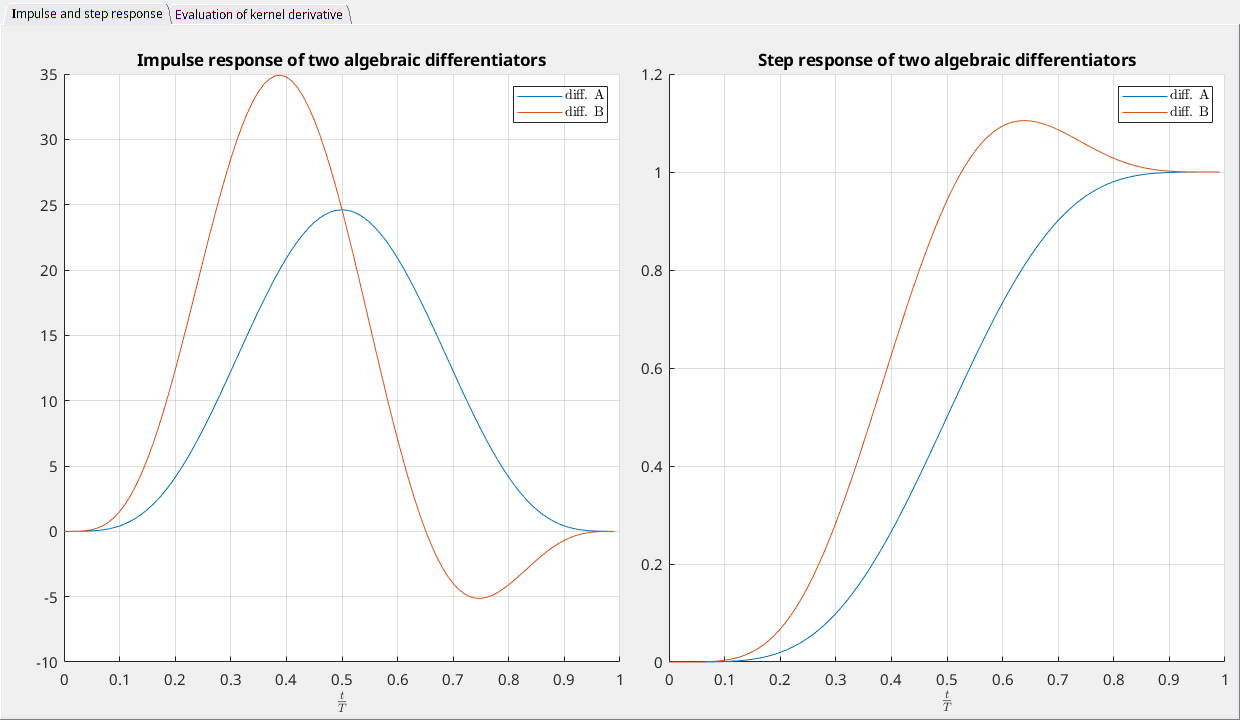

clear
close all
% Install the package AlgDiff using pip (see the Readme file
% in the repository for more informations: pip3 install AlgDiff)
% Some python code running inside matlab may fail with an error 
% mentioning Parameter * was incorrect on entry to . This can be 
% avoided by calling the following in the startup script
% py.sys.setdlopenflags(int32(bitor(int64(py.os.RTLD_LAZY), int64(py.os.RTLD_DEEPBIND))));


ts = 0.001;
T = 0.1;
NA = 0;
NB = 1;
alpha = 4.0;
beta = 4.0;
wc = [];
t = 0:ts:(T-ts);

diffA = AlgDiff(ts,alpha,beta,NA, "FilterWindowLength" ,T, "CutoffFrequency", wc);
diffB = AlgDiff(ts,alpha,beta,NB, "FilterWindowLength" ,T, "CutoffFrequency", wc);

% Compute the impulse and step response of the differentiator
gA = diffA.evalKernel(t);
hA = diffA.get_stepResponse(t);
tA = t/diffA.get_T();

gB = diffB.evalKernel(t);
hB = diffB.get_stepResponse(t);
tB = t/diffB.get_T();

fi = figure('Position', [370 180 1240 720]);
tabg = uitab('Title', 'Impulse and step response');
axg = axes('Parent',tabg,'Position',[.05,.08,.45,.85]);
hold(axg,'on');
plot(tA,gA,'Parent',axg);
plot(tB,gB,'Parent',axg);
grid(axg,'on');
xlabel('$\frac{t}{T}$','Interpreter','latex');
legend({'diff. A','diff. B'}, 'Interpreter', 'latex');
title('Impulse response of two algebraic differentiators');

axh = axes('Parent',tabg,'Position',[.54,.08,.45,.85]);
hold(axh,'on');
plot(tA,hA,'Parent',axh);
plot(tB,hB,'Parent',axh);
title('Step response of two algebraic differentiators');
grid(axh,'on');
xlabel('$\frac{t}{T}$','Interpreter','latex');
legend({'diff. A','diff. B'}, 'Interpreter', 'latex');


% Compute and plot the first derivatives of the kernel of the differentiator
n = 1;
dgA = diffA.evalKernelDer(t,n);
xA = t/diffA.get_T();
yA = dgA*diffA.get_T()^(1+n)/(2^n);

dgB = diffB.evalKernelDer(t,n);
xB = t/diffB.get_T();
yB = dgB*diffB.get_T()^(1+n)/(2^n);

% fd = figure('Position', [370 180 1240 720]);
tab1 = uitab('Title', 'Evaluation of kernel derivative');
ax1 = axes(tab1);
plot(xA,yA,'Parent',ax1);
hold(ax1,'on');
grid(ax1,'on');
plot(xB,yB,'Parent',ax1);
xlabel('$\frac{t}{T}$','Interpreter','latex');
legend({'diff A.','diff. B'}, 'Interpreter', 'latex');
title('First derivatives of the kernels of two algebraic differentiators');

## Frequency-domain analysis

The fourier transform of an algebraic differentiator is given as


$$\mathcal{G}(\omega) = \sum_{i=0}^{N} \frac{(\alpha + \beta + 2i + 1)\mathrm{P}_{i}^{(\alpha,\beta)}}{\alpha+\beta+i+1} \sum_{k=0}^{i} (-1)^{i-k} {i \choose k} \mathrm{M}_{i,k}^{(\alpha,\beta)}(-\iota\omega T)$$


where $\mathrm{M}_{i,k}^{(\alpha,\beta)}$ denotes the hypergeometric Kummer M-Function. An approximation of the amplitude spectrum of the algebraic differentiator is

                                         
$$\left|\mathcal{G}(\omega)\right|\approx\begin{cases}
1,&\quad \left|{\omega}\right|\leq\omega_{\mathrm{c}},\\
\left|{\frac{\omega_{\mathrm{c}}}{\omega}}\right|^{\mu},&\quad \text{otherwise},
\end{cases}$$


with $\omega_{\mathrm{c}}$ the cutoff frequency of the algebraic differentiator and $\mu=1+\min\{\alpha,\beta\}$.

Lower and upper bounds can be computed for the amplitude spectrum of the algebraic differentiators. If $N=0$ and $\alpha=\beta$, the amplitude reaches 0 and the lower bound is 0.

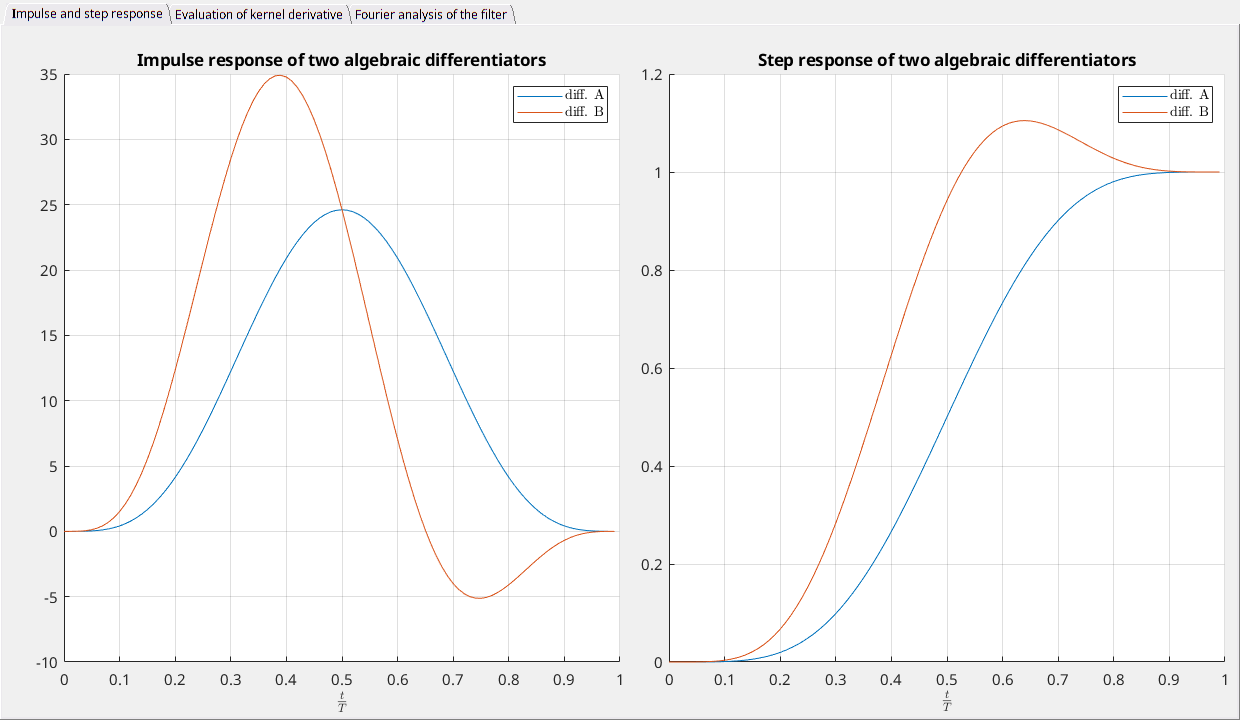

% Define frequencies where the Fourier transformation should be 
% computed
omega = linspace(1, 800, 4e3);

% Get amplitude, phase, and bounds of Fourier transform of filter A
[ampA, phaseA] = diffA.get_ampAndPhaseFilter(omega);
[ubA, lbA, mbA] = diffA.get_asymptotesAmpFilter(omega);

% Get amplitude, phase, and bounds of Fourier transform of filter B
[ampB, phaseB] = diffB.get_ampAndPhaseFilter(omega);
[ubB, lbB, mbB] = diffB.get_asymptotesAmpFilter(omega);

tabF = uitab('Title','Fourier analysis of the filter');
ax2 = axes('Parent',tabF,'Position',[.05,.08,.45,.8]);
plot(omega/diffA.get_cutoffFreq(),20*log10(ampA));
hold(ax2, 'on');
grid(ax2, 'on');
plot(omega/diffA.get_cutoffFreq(),20*log10(ubA));
plot(omega/diffA.get_cutoffFreq(),20*log10(lbA));
plot(omega/diffA.get_cutoffFreq(),20*log10(mbA));
ylim([-110 1]);
legend({'$|\mathcal{G}_{A}(\omega)|$','$|\mathcal{G}_{A}^{+}(\omega)|$',...
    '$|\mathcal{G}_{A}^{-}(\omega)|$','$|\mathcal{G}_{A}^{\Delta}(\omega)|$'},... 
    'Interpreter','latex');
ylabel('Amplitude in db');
xlabel({'$\frac{\omega}{\omega_{\mathrm{c,A}}}$'},'Interpreter','latex');
title(["Amplitude of the Fourier", "transform of differentiator A"])

ax3 = axes('Parent',tabF,'Position',[.54,.08,.45,.8]);
plot(omega/diffB.get_cutoffFreq(),20*log10(ampB));
hold(ax3, 'on');
grid(ax3, 'on');
plot(omega/diffB.get_cutoffFreq(),20*log10(ubB));
plot(omega/diffB.get_cutoffFreq(),20*log10(lbB+10^(-50)));
plot(omega/diffB.get_cutoffFreq(),20*log10(mbB));
ylim([-180 1]);
legend({'$|\mathcal{G}_{B}(\omega)|$','$|\mathcal{G}_{B}^{+}(\omega)|$',...
    '$|\mathcal{G}_{B}^{-}(\omega)|$','$|\mathcal{G}_{B}^{\Delta}(\omega)|$'},... 
    'Interpreter','latex');
title(["Amplitude of the Fourier", "transform of differentiator B"])
xlabel({'$\frac{\omega}{\omega_{\mathrm{c,B}}}$'},'Interpreter','latex');

## Estimation of derivatives

### Simulated signal

The derivative of a signal $y : t \mapsto y(t)$ without any disturbance is estimated: The first differentiator has a delay. The second differentiator is parametrized for a delay free approximation. Be aware that a delay

free estimation is less accurate than a delayed one!

%% Define true signal and its true derivatives
% Define signal
syms a_0 a_1 a_2 t
y = a_0*exp(-a_1*t)*sin(a_2*t);
method = 'trapezoidal';

% Derivative to be estimated
dy = diff(y,t);
d2y = diff(dy,t);

% Evaluate signal and true derivative
teval = 0:ts:20-ts;
y = subs(y,[a_0,a_1,a_2],[1,0.1,4]);
dy = subs(dy,[a_0,a_1,a_2],[1,0.1,4]);
d2y = subs(d2y,[a_0,a_1,a_2],[1,0.1,4]);

yeval = matlabFunction(y);      % Converting to Matlab function
dyeval = matlabFunction(dy);    % for faster execution
d2yeval = matlabFunction(d2y);
yeval = yeval(teval);
dyeval = dyeval(teval);
d2yeval = d2yeval(teval);

%% Parametrize diffB to be delay-free
% Set the parameter \vartheta
diffB.set_theta(1, "off");
% Print the characteristics of the differentiator
disp(diffB);

  AlgDiff with properties:

    inst: [1×1 py.AlgDiff.algebraicDifferentiator.AlgebraicDifferentiator]

	Parameters of the differentiator:
		Alpha: 4.000000
		Beta: 4.000000
		Window length in s: 0.100000
		Sampling period in s: 0.001000
		Polynomial degree: 1
		Estimation delay in s: 0.000000
		Cutoff Frequency in rad/s: 112.653998
		Cutoff Frequency in Hz: 17.929441
		Discrete window length: 100




%% Estimate derivatives
% Filter the signal y
xAppA = diffA.estimateDer(0,yeval);
xAppB = diffB.estimateDer(0,yeval);

% Estimate its first derivative
dxAppA = diffA.estimateDer(1,yeval);
dxAppB = diffB.estimateDer(1,yeval);

% Estimate its 2nd derivative
d2xAppA = diffA.estimateDer(2,yeval);
d2xAppB = diffB.estimateDer(2,yeval);

% Plot results
tab5 = uitab('Title','Simulated Signal');
axy = axes('Parent',tab5,'Position',[.06 .08 .28 .9]);
hold(axy,'on');
grid(axy,'on');
plot(teval,yeval);
plot(teval,xAppA);
plot(teval,xAppB);
xlabel('t');
ylabel('signals');

axdx = axes('Parent',tab5,'Position',[.38 .08 .28 .9]);
hold(axdx,'on');
grid(axdx,'on');
plot(teval,dyeval);
plot(teval,dxAppA);
plot(teval,dxAppB);
xlabel('t');

axd2x = axes('Parent',tab5,'Position',[.7 .08 .28 .9]);
hold(axd2x,'on');
grid(axd2x,'on');
plot(teval,d2yeval);
plot(teval,d2xAppA);
plot(teval,d2xAppB);
xlabel('t');
legend('true','diff. A','diff. B');

### Measured signal

The measurements are loaded from a .mat file. The first and second derivative of the signal are estimated using an algebraic differentiator.

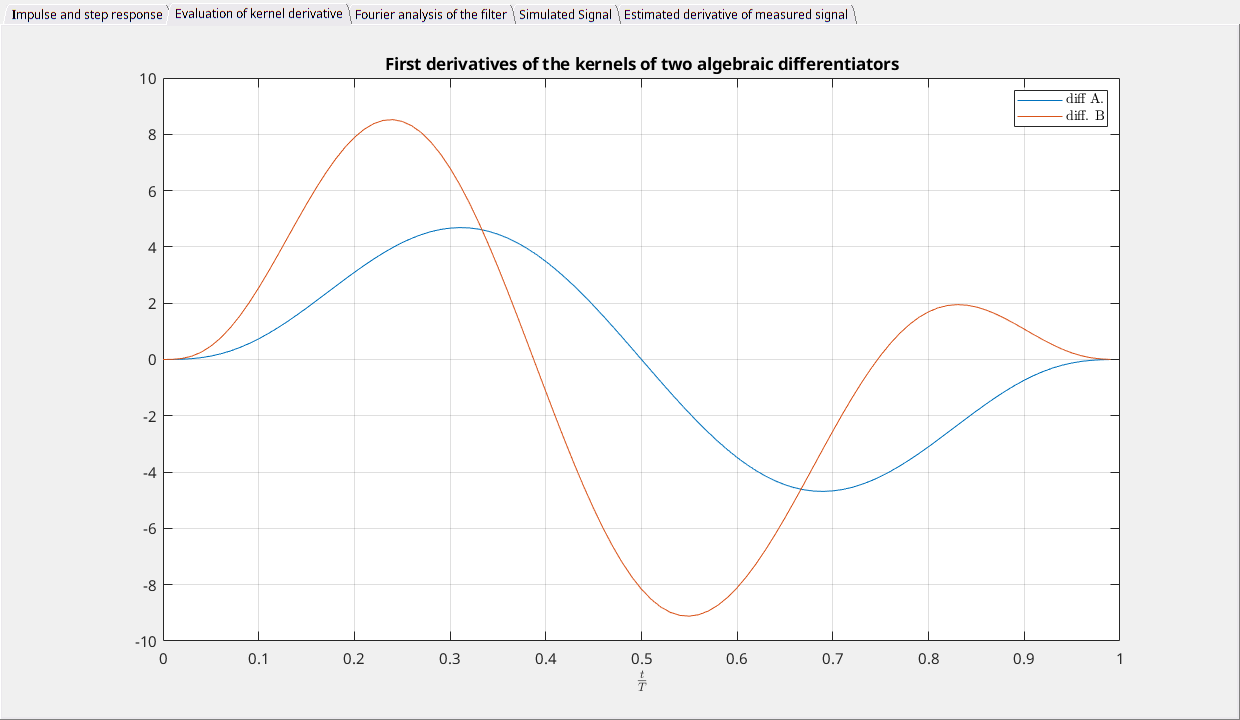

% Load measurements
data = table2array(readtable('../examples/data90.dat'));
ts = data(3,1)-data(2,1);
tmeas = data(:,1)';
xmeas = data(:,3)';

% Estimate derivatives
alpha = 4;
beta = 4;
NA = 1;
T = [];
wc = 20;

diffD = AlgDiff(ts,alpha,beta,NA, "FilterWindowLength", T, "CutoffFrequency", wc);
xAppA = diffD.estimateDer(0,xmeas);
dxAppA = diffD.estimateDer(1,xmeas);
d2xAppA = diffD.estimateDer(2,xmeas);

% Plot results
tab3 = uitab('Title','Estimated derivative of measured signal');
ax4 = axes('Parent',tab3,'Position',[.06 .08 .28 .9]);
hold(ax4,'on');
grid(ax4,'on');
plot(tmeas,xmeas);
plot(tmeas,xAppA);
ylabel('Signals');
xlabel('t in seconds');
legend({'$y(t)$','$\hat{y}(t)$'},'Interpreter','latex');
ax5 = axes('Parent',tab3,'Position',[.38 .08 .28 .9]);
hold(ax5,'on');
grid(ax5,'on');
plot(tmeas,dxAppA);
xlabel('t in seconds');
legend('$\dot{\hat{y}}(t)$','Interpreter','latex');
ax6 = axes('Parent',tab3,'Position',[.70 .08 .28 .9]);
hold(ax6,'on');
grid(ax6,'on');
plot(tmeas,d2xAppA);
xlabel('t in seconds');
legend('$\ddot{\hat{y}}(t)$','Interpreter','latex');

## References

(Mboup, Join *et al.*, 2007) M. Mboup, C. Join and M. Fliess, "*A revised look at numerical differentiation with an application to nonlinear feedback control"*, 15th Mediterranean Conf. on Control & Automation, June 2007.  [online](https://ieeexplore.ieee.org/document/4433728)

(Mboup, Join *et al.*, 2009) Mboup M., Join C. and Fliess M., "*Numerical differentiation with annihilators in noisy environment"*, Numerical Algorithms, vol. 50, number 4, pp. 439--467,  2009.  [online](https://link.springer.com/article/10.1007/s11075-008-9236-1)

(Liu, Gibaru *et al.*, 2011) Liu D.-Y., Gibaru O. and Perruquetti W., "*Differentiation by integration with Jacobi polynomials"*, Journal of Computational and Applied Mathematics, vol. 235, number 9, pp. 3015 - 3032,  2011.  [online](http://www.sciencedirect.com/science/article/pii/S0377042710006734)

(Kiltz, 2017) L. Kiltz, "*Algebraische Ableitungsschätzer in Theorie und Anwendung"*,  2017.  [online](https://scidok.sulb.uni-saarland.de/handle/20.500.11880/26974)